# ------------------ MIE WRAPPER -----------------

% -----------------------------------------------------------


% This script will run the .INP files using runMIE.m, and then read the .OUT files using readMIE.m.
% The intention of the script is to control the MIE calculation program
% MIE from Matlab. The user will be able to create files, run them and
% view the results here in this live script


clear variables; 


% Created by Andrew J. Buggee

## DESIGNATE FOLDER, INPUT AND OUTPUT FILES

% for now, we will manually create uvspec.inp files, and simply call them
% out as variables


% ---------------------------------------------
% ------------------- MACBOOK -----------------
% ---------------------------------------------

folderName = '/Users/andrewbuggee/Documents/libRadtran-2.0.6/testing_mie/';


% inputName = 'compare_water_with_ice.INP';
inputName = 'compare_ice_with_water.INP';

outputName = inputName(1:end-4);

% ---------------------------------------------
% ---------------- MAC DESKTOP ---------------
% ---------------------------------------------

% folderName = '/Users/andrewbuggee/Documents/libRadtran-2.0.6/Mie_netCDF_files/';
% 
% 
% inputName = 'Mie_calc_water_GammaDist_HySICS_testFile.INP';

% outputName = inputName(1:end-4);











## RUN MIE AND SAVE INPUTS/OUTPUTS

tic
[drop_settings] = runMIE(folderName,inputName,outputName, whatComputer);
toc

Elapsed time is 0.106237 seconds.


## READ UVSPEC OUTPUT FILES

if iscell(outputName)==true

    ds = cell(1,length(outputName));

    for jj = 1:length(outputName)

        [ds{jj},headers,num_radii] = readMIE(folderName,outputName{jj}); % headers don't change per iteration

    end

else

    [ds,headers,num_radii] = readMIE(folderName,outputName);

end





## PLOT AND ANALYZE OUTPUT FILES

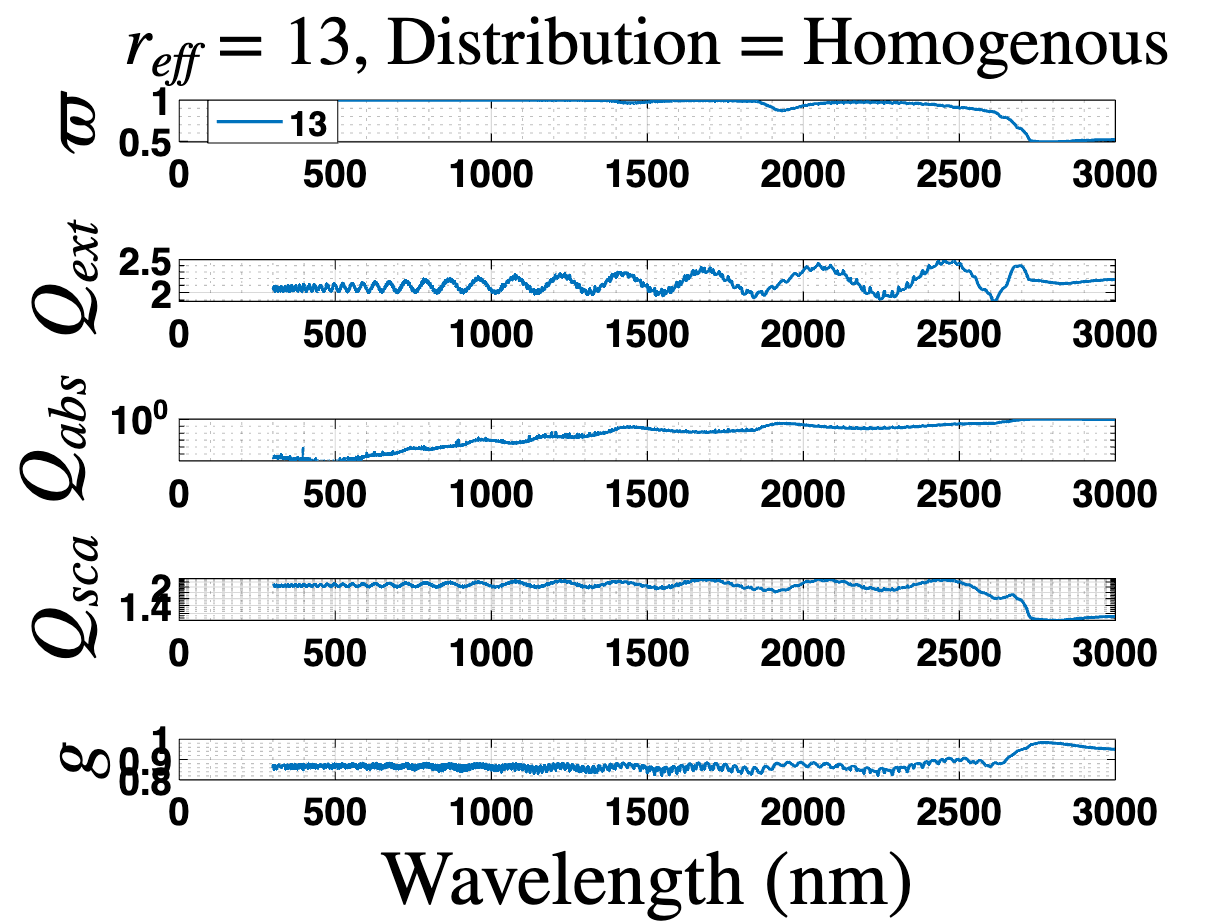

% Use the following numbers for the desired plot properties
% plotFlag = 1 if livescript plotting is desired
% plotFlag = 2 if black background plots are desired
% plotFlag = 3 if white background plots are desired

plotFlag = 3; % if livescript plotting is deisred

if plotFlag == 1
    liveScriptPlotting;
    
elseif plotFlag == 2
    scriptPlotting_blk;
    
elseif plotFlag == 3
    scriptPlotting_wht;
    
else
    error('Incorrect option for Plot Flag');
end

% First lets plot the Single Scattering, asymmetry and extinction
% coefficient
if iscell(ds)==false

    figure;
    
    subplot(5,1,1)
    p1 = plot(ds.wavelength,ds.ssa,'LineWidth',1.5);
    grid on; grid minor
    title(['$r_{eff} = $',num2str(drop_settings{1}),', Distribution = ',drop_settings{2}], ...
        'Interpreter','latex')

    ylabel('$\varpi$', 'Interpreter','latex')
    %p1.Parent.Position(3) = 1; % this will make the subplots wider by 300 pixels
    % xlim([min(ds.wavelength) max(ds.wavelength)])
    for rr = 1:num_radii
        legend_str{rr} = num2str(drop_settings{1}(rr));
    end
    
    legend(legend_str,'Location',"best")
    
    subplot(5,1,2)
    p2 = semilogy(ds.wavelength,ds.Qext,'LineWidth',1.5);
    grid on; grid minor
    ylabel('$Q_{ext}$', 'Interpreter','latex')
    
    subplot(5,1,3)
    p3 = semilogy(ds.wavelength, ds.Qext - ds.Qsca,'LineWidth',1.5);
    grid on; grid minor
    ylabel('$Q_{abs}$', 'Interpreter','latex')

    subplot(5,1,4)
    p4 = semilogy(ds.wavelength, ds.Qsca,'LineWidth',1.5);
    grid on; grid minor
    ylabel('$Q_{sca}$', 'Interpreter','latex')

    subplot(5,1,5)
    p5 = plot(ds.wavelength, ds.asymParam,'LineWidth',1.5);
    grid on; grid minor
    xlabel('Wavelength (nm)', 'Interpreter','latex')
    ylabel('$g$', 'Interpreter','latex')

else


end


if plotFlag == 2
    set(gcf,'color','k');
end


## Plot Size Distribution

% if strcmp(drop_settings{2},'log normal')==true
%     r_eff = drop_settings{1};
%     sigma = str2double(drop_settings{3});
%     n_r = a./r * exp(-1/2 * ((log(r) - log(r_eff))./log()))
%     
% elseif strcmp(drop_settings{2},'gamma') == true
%     
%     
% else
%     
% end

% end